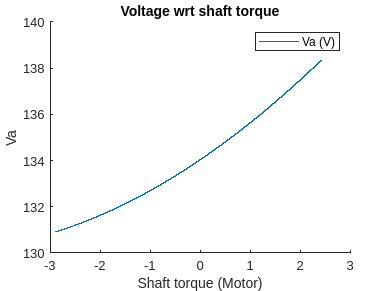

 % SEM HJ116J6-130S 
% R = 0.85;
% L = 4.75e-3;
% p = 6;
% iph_max = 7.8;
% vph_max = 286;

load("Measurement_Data/Measurement_2023_12_14_16_50.mat")

% SEM HJ130G8-130S
R = 0.75;
L = 3.15e-3;
p = 8;

% 4.4
beta = 0;
ia = -5:0.001:5; % armature current

omega_m = 2*pi*2400/60;
omega_e = omega_m*p/2; % electric omega
lambda_m = 0.133;

% Electrical characteristics
ef = lambda_m * omega_e;
va = ef + ia * (R + i*omega_e*L);

% Torque
% tf_tot = 0.001638 * omega_m + 0.4942;

tf_tot = 0.002401 * omega_m + 0.5246;
tf_pmsm = 0.2 * tf_tot;
td = ef*ia*cos(beta)/omega_m;
ts = td - tf_pmsm;


% Motor
ts_new = (td-tf_pmsm);
% ts_new(ts_new == 0) = NaN;

figure;
hold on;
plot(ts_new, abs(va));

title('Voltage wrt shaft torque');
xlabel('Shaft torque (Motor)');
ylabel('Va');
legend('Va (V)');
hold off;

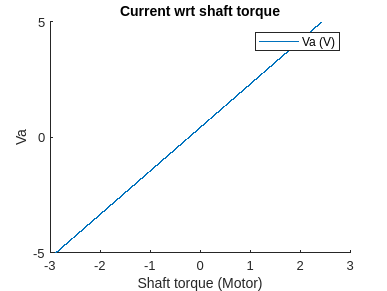


figure;
hold on;
plot(ts_new, ia);
title('Current wrt shaft torque');
xlabel('Shaft torque (Motor)');
ylabel('Va');
legend('Va (V)');
hold off;

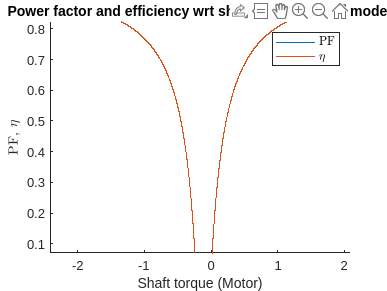


% 5
PF = cos(angle(va));
% Motor
eff = (ts > 0).*(td > 0).*(ts*omega_m)./abs(va.*ia.*PF);
% Generator
eff = eff + (ts < 0).*(td < 0).*abs(va.*ia.*PF)./abs(ts*omega_m);
figure;
hold on;
plot(ts_new, PF);
plot(ts_new, eff);
title('Power factor and efficiency wrt shaft torque (Motor mode)');
xlabel('Shaft torque (Motor)');
ylabel('PF, $\eta$', 'Interpreter', 'latex');
legend('PF', '$\eta$', 'Interpreter', 'latex');
hold off;

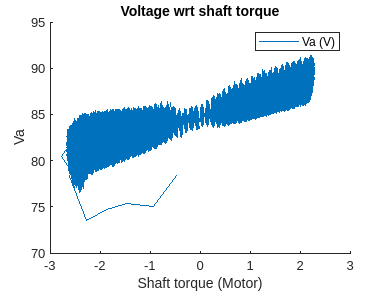

% 5
% SEM HJ116J6-130S 
% R = 0.85;
% L = 4.75e-3;
% p = 6;
% iph_max = 7.8;
% vph_max = 286;

% SEM HJ130G8-130S
R = 0.75;
L = 3.15e-3;
p = 8;

load("Measurement_Data/Measurement_2023_12_14_16_50.mat")

ia = Ia_rms_ACM; % armature current

omega_m = 2*pi*n;
omega_e = omega_m*p/2; % electric omega
lambda_m = 0.133;

% Electrical characteristics
% ef = lambda_m * omega_e;
% va = ef + ia * (R + i*omega_e*L);

va = Van_rms_ACM.*exp(i*acos(PF_ACM));
ef = va - ia.*(R + i.*omega_e*L);
% Torque
% tf_tot = 0.001638 * omega_m + 0.4942;

beta = angle(ef);
tf_tot = 0.002401 * omega_m + 0.5246;
tf_pmsm = 0.2 * tf_tot;
td = abs(ef).*ia.*cos(angle(ef))./omega_m;
ts = td - tf_pmsm;


% Motor
ts_new = (td-tf_pmsm);
% ts_new(ts_new == 0) = NaN;

figure;
hold on;
plot(ts_new, abs(va));

title('Voltage wrt shaft torque');
xlabel('Shaft torque (Motor)');
ylabel('Va');
legend('Va (V)');
hold off;

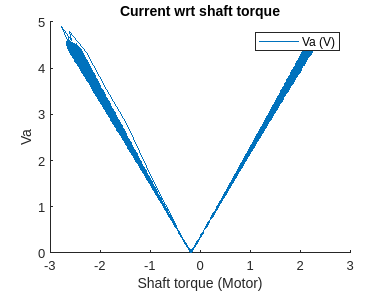


figure;
hold on;
plot(ts_new, ia);
title('Current wrt shaft torque');
xlabel('Shaft torque (Motor)');
ylabel('Va');
legend('Va (V)');
hold off;

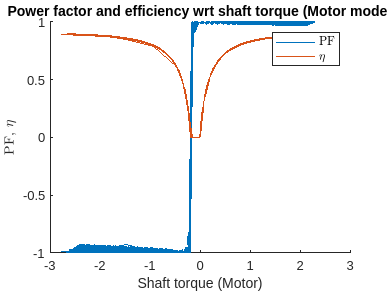


% 5
PF = cos(angle(va));
% Motor
eff = (ts > 0).*(td > 0).*(ts.*omega_m)./abs(va.*ia.*PF);
% Generator
eff = eff + (ts < 0).*(td < 0).*abs(va.*ia.*PF)./abs(ts.*omega_m);
figure;
hold on;
plot(ts_new, PF);
plot(ts_new, eff);
title('Power factor and efficiency wrt shaft torque (Motor mode)');
xlabel('Shaft torque (Motor)');
ylabel('PF, $\eta$', 'Interpreter', 'latex');
legend('PF', '$\eta$', 'Interpreter', 'latex');
hold off;